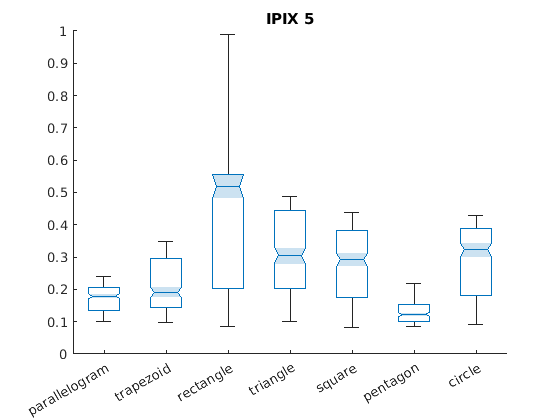

% IPIX
load('shape_results_IPIX_plus5_size100_pop250_run1.mat')
labels = {'parallelogram','trapezoid','rectangle','triangle','square','pentagon','circle'};

data = []; data_cat = [];
for i = 1:length(labels)
    
    err = shape_error(i,:);
    err(err > 1) = [];
    
    data = [data err]; 
    data_cat = [data_cat i*ones(size(err))]; %repmat(labels(i),1,length(err))];
    
end

figure
boxchart(categorical(data_cat),data,'notch','on')
xticklabels(labels)
title('IPIX 5')

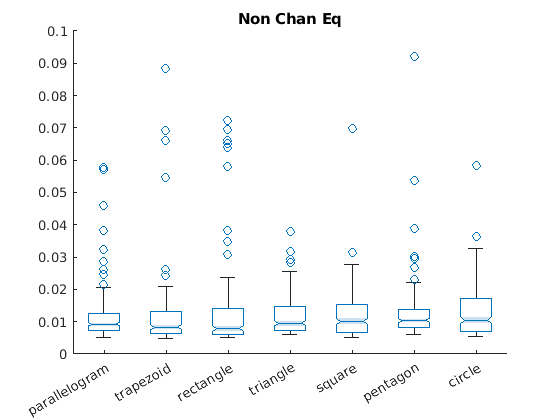

load('shape_results_non_chan_eq_rodan_size100_pop250_run3.mat')
labels = {'parallelogram','trapezoid','rectangle','triangle','square','pentagon','circle'};

data = []; data_cat = [];
for i = 1:length(labels)
    
    err = shape_error(i,:);
    err(err > 0.1) = [];
    
    data = [data err]; 
    data_cat = [data_cat i*ones(size(err))]; %repmat(labels(i),1,length(err))];
    
end

figure
boxchart(categorical(data_cat),data,'notch','on')
xticklabels(labels)
title('Non Chan Eq')

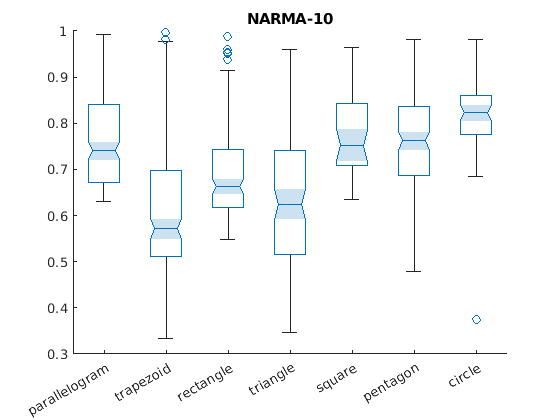

load('shape_results_narma_10_size100_pop250_run1.mat')
labels = {'parallelogram','trapezoid','rectangle','triangle','square','pentagon','circle'};

data = []; data_cat = [];
for i = 1:length(labels)
    
    err = shape_error(i,:);
    err(err > 1) = [];
    
    data = [data err]; 
    data_cat = [data_cat i*ones(size(err))]; %repmat(labels(i),1,length(err))];
    
end

figure
boxchart(categorical(data_cat),data,'notch','on')
xticklabels(labels)
title('NARMA-10')

%set(gca, 'YScale', 'log')
%ylim([0.1 1])

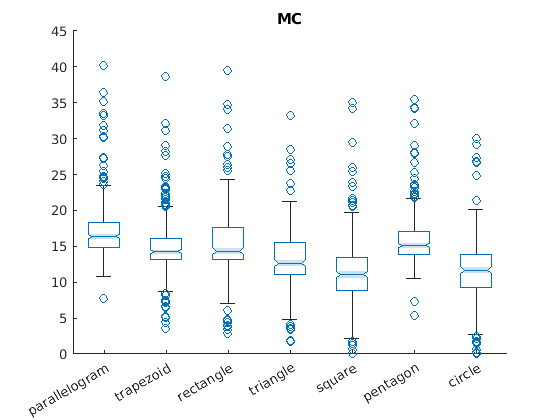

load('shape_results_MC_size100_pop250_run4.mat')
labels = {'parallelogram','trapezoid','rectangle','triangle','square','pentagon','circle'};

data = []; data_cat = [];
for i = 1:length(labels)
    
    err = 100-shape_error(i,:);    
    data = [data err]; 
    data_cat = [data_cat i*ones(size(err))]; %repmat(labels(i),1,length(err))];
    
end

figure
boxchart(categorical(data_cat),data,'notch','on')
xticklabels(labels)
title('MC')

figure
x=[shape_pop{2}.test_error]

x =    85.2763   86.5352   90.2021   84.5805   92.6468   86.8323   87.7214   89.5915   86.9583   87.8720   86.8040   86.2551   83.5078   79.5705   84.5115   88.1867   83.7485   93.5680   85.1030   86.2153   87.0337   86.6821   84.8924   82.7364   84.4706   78.4684   91.2673   86.5163   86.5464   84.5319   86.5357   86.1844   86.4252   84.5964   88.3874   85.9512   83.7818   87.1634   84.7388   78.2392   86.3349   85.2802   87.8924   85.3404   74.7917   81.4798   86.9195   80.9910   85.3126   82.3656


pop=[shape_pop{2}.layer];
y = [pop.damping]

y =     0.6545    0.5585    0.1629    0.4541    0.1897    0.9852    0.7471    0.1747    0.8569    0.2689    0.2447    0.3364    0.6764    0.2865    0.5444    0.1325    0.4673    0.1640    0.3648    0.9102    0.6934    0.6751    0.3139    0.5538    0.2480    0.2301    0.1593    0.5810    0.8741    0.6911    0.7839    0.3326    0.3666    0.5637    0.2580    0.3284    0.1340    0.8606    0.8386    0.4239    0.5599    0.4998    0.9478    0.7435    0.2251    0.2826    0.8977    0.3413    0.7592    0.3643


z = [pop.input_scaling]

z =     0.4283    0.8335    0.6058    0.5404    0.9553    0.2562    0.8332    0.5558    0.7283   -0.6787    0.6002    0.6265    0.0859   -0.1978   -0.4436    0.4689    0.4365    0.9319   -0.5529    0.2351    0.8158    0.9320   -0.5259    0.1399    0.5164   -0.2040   -0.7047   -0.7528    0.4635   -0.2336   -0.6361    0.5831    0.7700   -0.4415    0.7803    0.5964    0.4088    0.8708   -0.0731   -0.0286   -0.6976    0.5756    0.9941    0.3082   -0.0927    0.3787    0.5450    0.2587    0.2746    0.4158


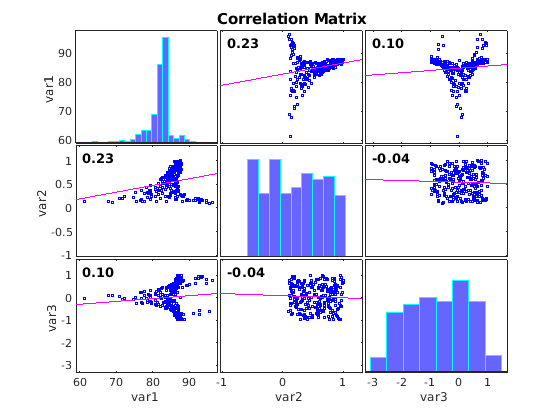

corrplot([x;y;(z)]')

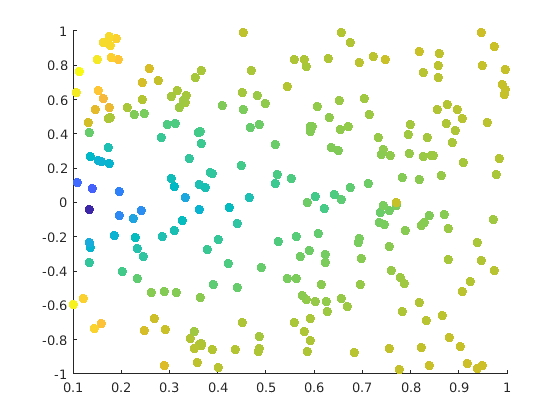


scatter(y,z,50,x,'filled')

%% Plot weights of shapes

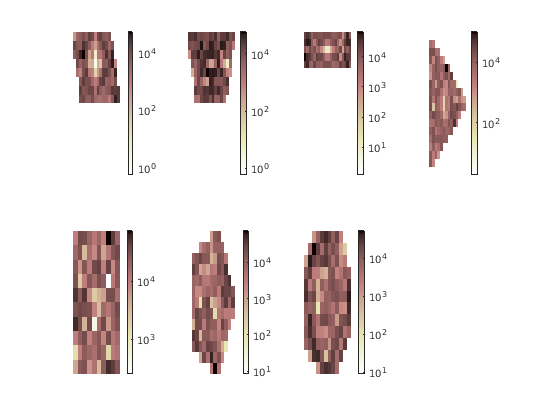

load('shape_results_narma_10_size100_pop250_run1.mat')
labels = {'parallelogram','trapezoid','rectangle','triangle','square','pentagon','circle'};

figure
title('NARMA-10')
for i = 1:7
[~,index] = sortrows([shape_pop{1, i}.test_error].'); 
shape_pop{1, i} = shape_pop{1, i}(index); 
clear index

w =shape_pop{1,i}(1).output_weights;

w = abs(w);

subplot(2,4,i)
imagesc(reshape(w(1:end-2),sqrt(length(w)-2),sqrt(length(w)-2)))
colormap(gca, flipud(pink))
colorbar
xlabel(labels{i})
set(gca,'ColorScale','log')

set(gca,'xtick',[])
set(gca,'xticklabel',[])
set(gca,'ytick',[])
set(gca,'yticklabel',[])
set(gca,'Visible','off')
end

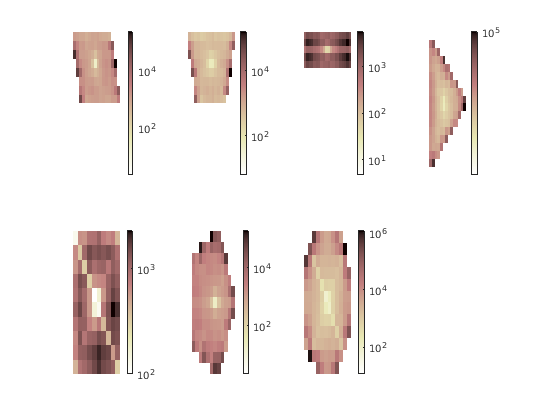


load('shape_results_MC_size100_pop250_run4.mat')
figure
title('MC')
for i = 1:7
[~,index] = sortrows([shape_pop{1, i}.test_error].',"descend"); 
shape_pop{1, i} = shape_pop{1, i}(index); 
clear index

w =shape_pop{1,i}(1).output_weights;

w = sum(abs(w),2);

subplot(2,4,i)
imagesc(reshape(w(1:end-2),sqrt(length(w)-2),sqrt(length(w)-2)))
colormap(gca, flipud(pink))
colorbar
title('labels{i}')
set(gca,'ColorScale','log')

set(gca,'xtick',[])
set(gca,'xticklabel',[])
set(gca,'ytick',[])
set(gca,'yticklabel',[])
set(gca,'Visible','off')
end